clear;clc;close all;

% Read the JSON file
InArgs = jsondecode(fileread('wave_profile.json'));
globalArgs = jsondecode(fileread('config.json'));

% Specify the file path
tb = read_dumpfile('db.dat');
tb1 = read_dumpfile('db1.dat');


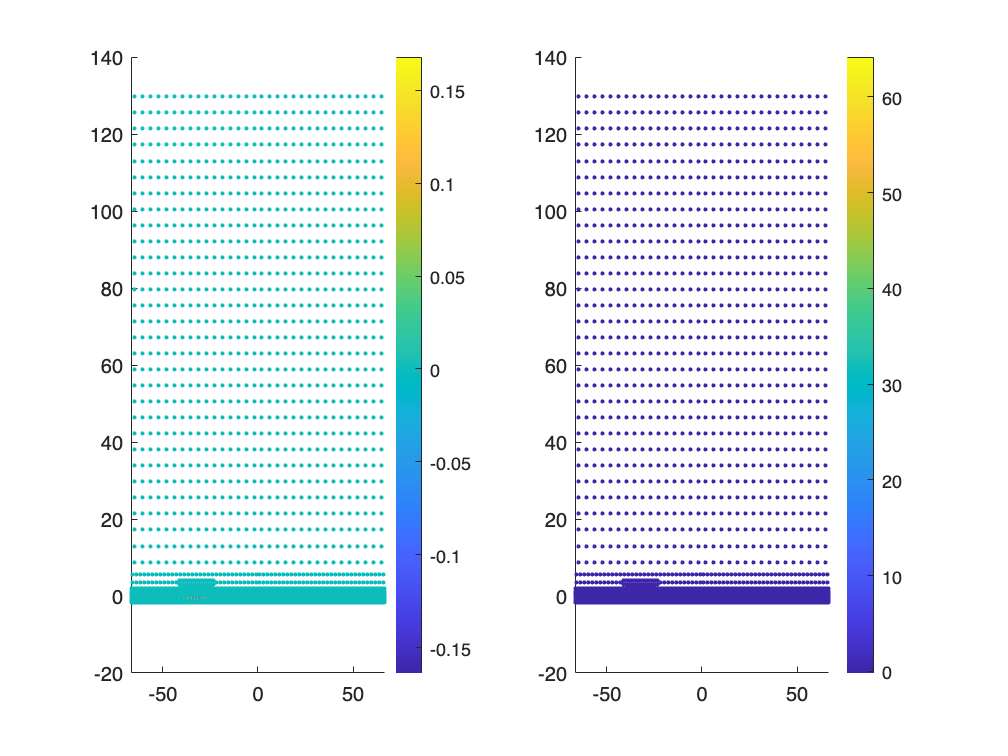

ls = spline(InArgs.bsk.xout, InArgs.bsk.etaout, tb.gpx)-tb.gpy;
zeta = min(0.0, -ls); % -h -> 0
vof = min(1,max(0,ls/2./tb.dp));
clf, figure
ax1=subplot(1,2,1);
scatter(tb.gpx, tb.gpy, [], tb.uy, '.')
colorbar
ax2=subplot(1,2,2);
scatter(tb1.gpx, tb1.gpy, [], tb1.uy, '.')
colorbar
linkaxes([ax1,ax2],'xy')

%mask = tb.f > 0.001 & tb.isleaf > 0;
%pot_S22 = 0*tb.gpx;
%pot_S22(mask) = generate_potential_fun(InArgs.bsk.A,InArgs.bsk.Tw,InArgs.bsk.h,InArgs.bsk.rev_period,tb.gpx(mask).',tb.gpy(mask).');

%pot_S22(i) = generate_potential_fun (InArgs.bsk.A,InArgs.bsk.Tw,InArgs.bsk.h,InArgs.bsk.rev_period,tb.gpx,tb.gpy);

%clf, figure
%scatter(tb.gpx, tb.gpy, [], pot_S22, '.')
%colorbar

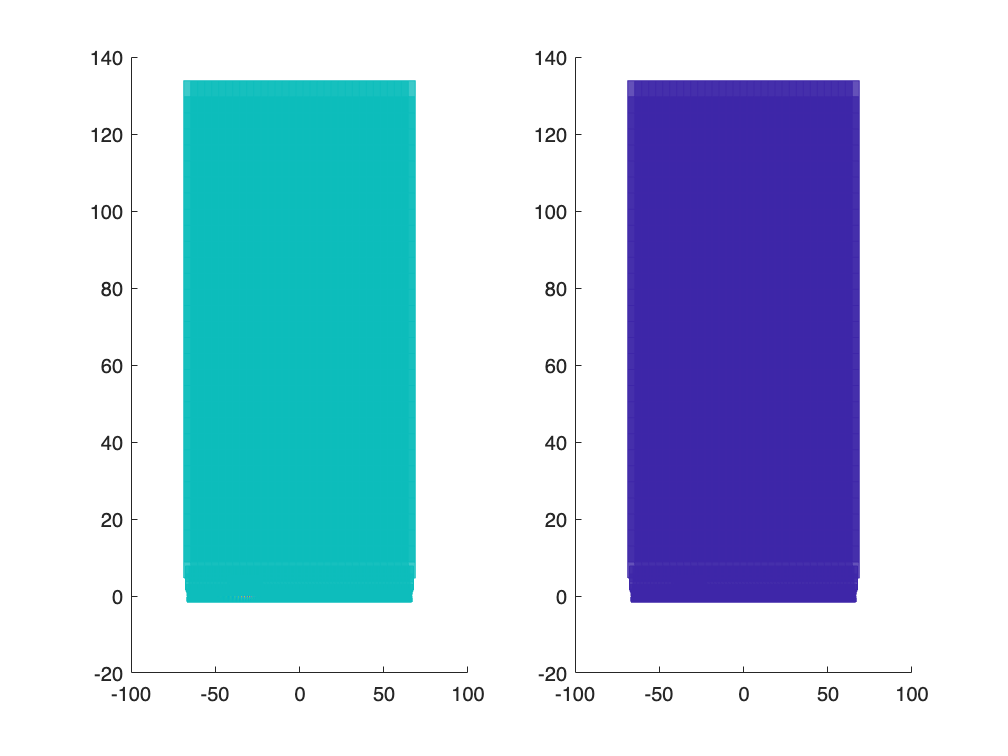

% Compute segments
% the curve is assumed to smooth 
% so that we can use simple height function.
vx = reshape([tb.gpx + tb.dp.*[-1, 1, 1, -1]].',[],1);
vy = reshape([tb.gpy + tb.dp.*[-1, -1, 1, 1]].',[],1);
vf = reshape([tb.uy + [0, 0, 0, 0]].',[],1);
nc = numel(tb.gpx);
F = ([1:nc].'-1)*4 + [1,2,3,4];
V = [vx, vy];
C = vf;

C2 = reshape([tb1.uy + [0, 0, 0, 0]].',[],1);

clf,figure
ax1=subplot(1,2,1);
%patch('Vertices', V, 'Faces', F, 'FaceColor', 'none', 'FaceAlpha',0.5, 'EdgeColor', 'k');
patch('Vertices', V, 'Faces', F, 'FaceColor', 'flat', 'FaceAlpha',0.8, 'EdgeColor', 'interp', 'FaceVertexCData', C);
ax2=subplot(1,2,2);
patch('Vertices', V, 'Faces', F, 'FaceColor', 'flat', 'FaceAlpha',0.8, 'EdgeColor', 'interp', 'FaceVertexCData', C2);
%axis equal
linkaxes([ax1,ax2],'xy')

function tb = read_dumpfile(file_path)

% Open the file for reading
file_id = fopen(file_path, 'r');

% Read the header string from line 1
header_string = textscan(file_id, '%s', 2, 'delimiter', '\n', 'headerlines', 0);

% Read the variable names from line 3
variable_names = textscan(file_id, '%s', 1, 'delimiter', '\n', 'headerlines', 0);
variable_names = strsplit(variable_names{1}{1}, ' ');
meshsize = variable_names((end-3):end);
meshsize = arrayfun(@str2num, string(meshsize));

% Close the file
fclose(file_id);

% Read the table data skipping the first three lines
tb = readtable(file_path, 'Delimiter', ' ', 'HeaderLines', 3, 'ReadVariableNames', false);

% Assign the variable names to the table
tb.Properties.VariableNames = replace(variable_names(1:end-4),'.','');

end